ans = 4×2 table
    Label    Count
    _____    _____

    go       3880 
    no       3941 
    stop     3872 
    yes      4044 


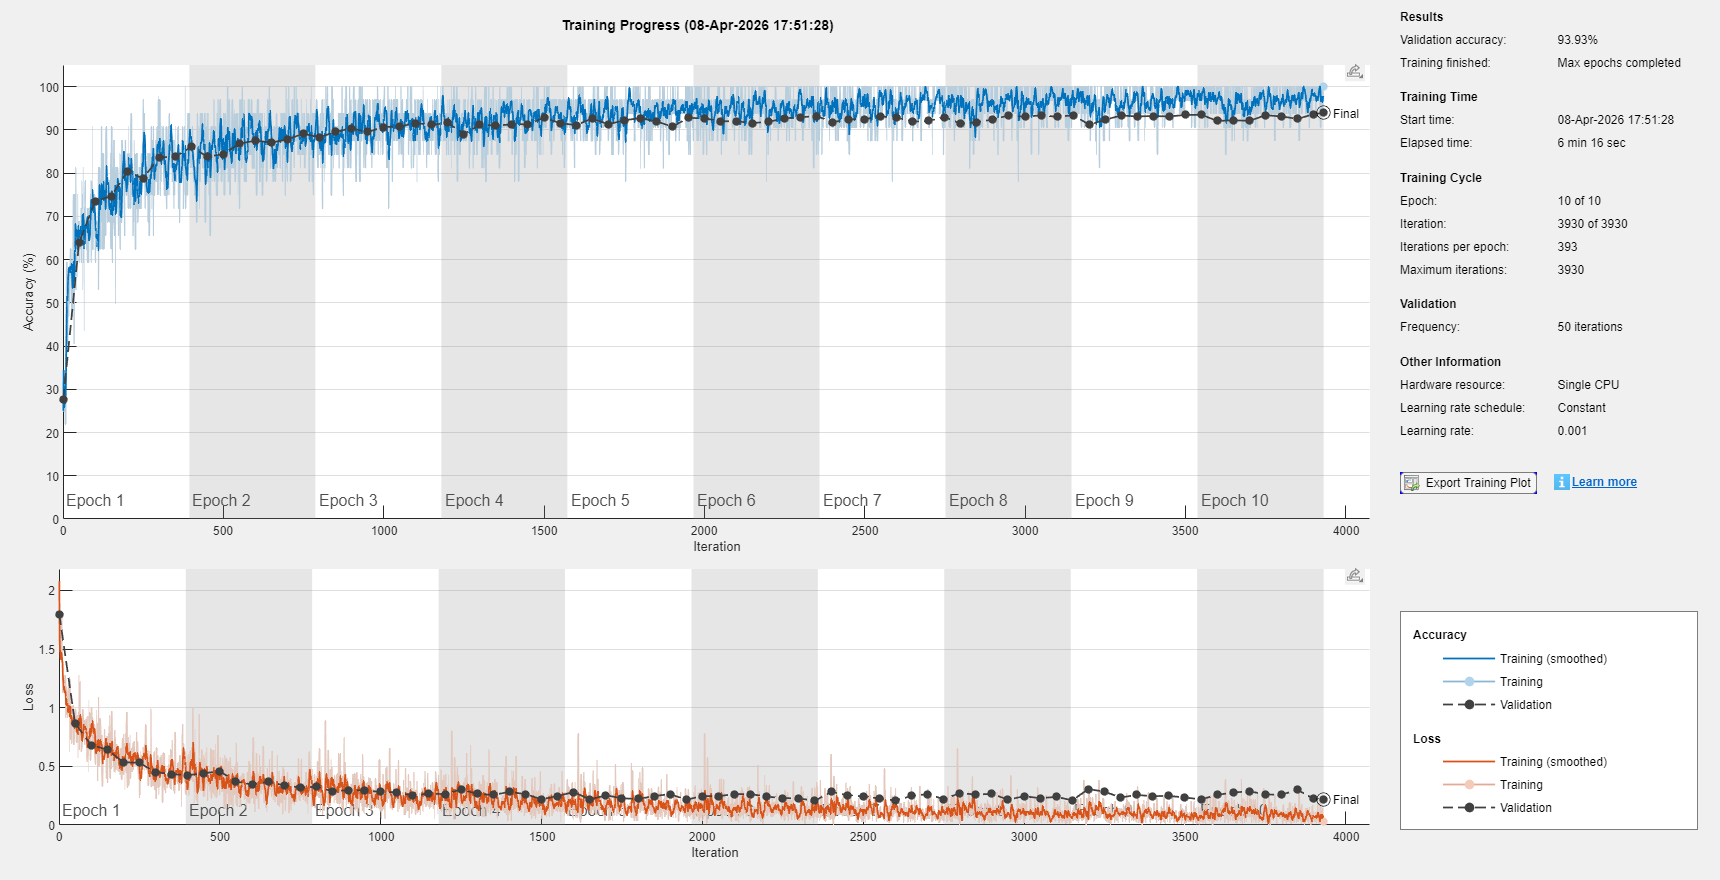

accuracy = 0.9393

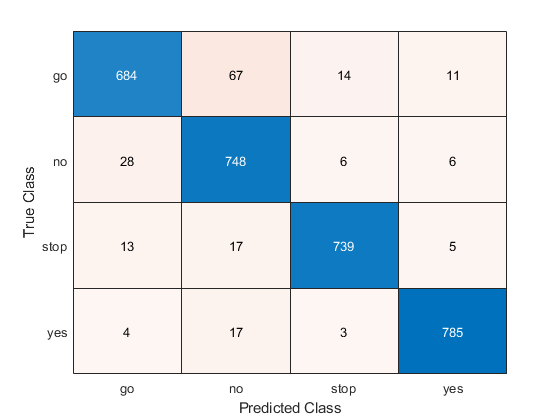

%SVM Model for Command Detection

clc; clear; close all;

%Load dataset
dataPath = "/Users/ericdutan/Documents/GitHub/ML_Project/Data_Set";

ads = audioDatastore(dataPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

%Extract features(MFC Mel-Frequency Cepstral Coefficients). These are handcrafted features
features = [];
labels = [];

for i = 1:length(ads.Files)
    
    % Read audio
    [audioIn, fs] = audioread(ads.Files{i});
    
    % Convert to mono if stereo
    if size(audioIn,2) > 1
        audioIn = mean(audioIn,2);
    end
    
    % Extract MFCCs
        %mfcc-> capture: pitch, tone, speech characteristics
    coeffs = mfcc(audioIn, fs);
    
    % Take mean and std (fixed-length feature vector)
    feat = [mean(coeffs), std(coeffs)];
    
    % Store
    features = [features; feat];
    labels = [labels; ads.Labels(i)];
end

%Split into training/testing (80/20)
cv = cvpartition(labels, 'HoldOut', 0.2);

XTrain = features(training(cv), :); %Training data inputs
YTrain = labels(training(cv));      %Corresponding training labels 

XTest = features(test(cv), :);  %Testing data inputs
YTest = labels(test(cv));       %Corresponding test outputs
    
%. Train SVM (multi-class since more than two classes)
    %SVM-> tries to draw boundaries between clusters/classes w/
    %Largest possible margin
model = fitcecoc(XTrain, YTrain);

%Saving model
modelPath = "/Users/ericdutan/Documents/GitHub/ML_Project/SVM_Build/svmModel.mat";
if isfile(modelPath)
    load(modelPath, "model");
else
    model = fitcecoc(XTrain, YTrain);
    save(modelPath, "model");
end


%% Predicting
YPred = predict(model, XTest);

%% Accuracy
accuracy = sum(YPred == YTest) / numel(YTest);

fprintf("Test Accuracy: %.2f%%\n", accuracy * 100);

%%wConfusion Matrix
figure;
confusionchart(YTest, YPred);
title("SVM Confusion Matrix");

